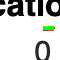

clear all

close all

 

% parameters

a=0:0.03:3; % range for a

d = 1;

c = 10;

del = 0.05;

M = 100;

 

 

%% Data from Python

r1 = [0.06426314 0.09666872 0.1291476  0.16170267 0.19433694 0.22705356

 0.25985585 0.29274729 0.32573154 0.35881241 0.39199396 0.42528043

 0.45867628 0.49218624 0.52581527 0.55956862 0.59345184 0.62747079

 0.66163169 0.69594113 0.73040608 0.76503398 0.79983272 0.8348107

 0.86997692 0.90534093 0.94091299 0.97670408 1.01272598 1.04899136

 1.08551386 1.12230822 1.15939035 1.19677752 1.23448851 1.27254376

 1.31096561 1.34977853 1.38900946 1.42868807 1.46884726 1.50952358

 1.55075787 1.59259596 1.63508955 1.67829731 1.72228628 1.76713354

 1.81292852 1.85977588 1.90779934 1.95714692 2.00799812 2.06057411

 2.11515245 2.17208953 2.23185568 2.29509342 2.36272069 2.43613025

 2.51762463 2.61155425 2.72840505 2.91991561 3.04086441 3.06384721

 3.04528874 3.04197156 3.0384177  3.04009725 3.03941533 3.04072618

 3.04160212 3.03443659 3.0442962  3.04439986 3.04097584 3.04239786

 3.03970714 3.045109   3.04173842 3.04720947 3.04369128 3.04170007

 3.04879448 3.04127257 3.04132549 3.04311453 3.04320417 3.04139295

 3.04104793 3.04184957 3.04103076 3.04150582 3.04162648 3.03957426

 3.04358147 3.04224417 3.0430001  3.03865915 0 0];

 

 

 

 r2 = [5.17533159 5.15509891 5.13488325 5.1146777  5.09447539 5.07426944

 5.05405298 5.03381908 5.01356079 4.9932711  4.97294291 4.95256901

 4.93214207 4.91165463 4.89109906 4.87046753 4.849752   4.82894421

 4.80803559 4.78701732 4.76588021 4.74461471 4.72321087 4.70165827

 4.679946   4.65806261 4.635996   4.61373342 4.59126134 4.56856542

 4.54563038 4.52243989 4.49897646 4.47522132 4.45115421 4.42675326

 4.40199472 4.37685275 4.35129909 4.32530275 4.29882957 4.27184176

 4.24429726 4.21614908 4.18734434 4.15782326 4.12751771 4.0963495

 4.06422816 4.03104803 3.99668435 3.96098813 3.9237789  3.8848346

 3.8438767  3.80054793 3.75437707 3.70472075 3.65066019 3.59080181

 3.52284228 3.44243037 3.33907941 3.16105005 3.04975955 3.04312889

 3.04279311 3.04004858 3.04539688 3.05127584 3.0581603  3.04516648

 3.0445567  3.04673876 3.03132854 3.02884017 3.04681289 3.05240139

 3.04605576 3.04821726 3.03310092 3.03696325 3.04427371 3.04487622

 3.04713981 3.04770177 3.04380366 3.04652796 3.04577141 3.0435053

 3.03849908 3.03483911 3.03961861 3.04858987 3.04365831 3.04460131

 3.04367051 3.04718946 3.04442507 3.04445756 0 0];

 

 

 

r3 =[ 9.91952856,  9.95241467,  9.98521183, 10.01792352, 10.05055305, 10.08310356,

 10.11557805, 10.14797941, 10.18031037, 10.21257354, 10.24477144, 10.27690647

 10.3089809  10.34099695 10.37295672 10.40486222 10.43671538 10.46851806

 10.50027204 10.53197902 10.56364065 10.5952585  10.62683408 10.65836885

 10.68986421 10.72132149 10.752742   10.78412697 10.81547761 10.84679507

 10.87808046 10.90933484 10.94055926 10.97175469 11.00292211 11.03406242

 11.06517652 11.09626527 11.1273295  11.15837    11.18938754 11.22038287

 11.25135671 11.28230974 11.31324264 11.34415605 11.37505059 11.40592687

 11.43678548 11.46762696 11.49845187 11.52926073 11.56005406 11.59083233

 11.62159602 11.6523456  11.6830815  11.71380416 11.74451399 11.77521139

 11.80589675 11.83657045 11.86723284 11.89788429 11.92860735 11.95764446

 11.99081637 12.02000961 12.05237811 12.08109989 12.11206904 12.14329402

 12.17439637 12.20321154 12.23389464 12.26354831 12.29566521 12.32576558

 12.35500175 12.3862242  12.41516076 12.44705364 12.47976851 12.50792061

 12.53941084 12.56974903 12.59982694 12.62927014 12.6614151  12.6933751

 12.72106037 12.75288735 12.78195818 12.81350628 12.84410883 12.87461189

 12.90495748 12.93719343 12.96585394 12.99626907 0 0 ];

 

 

% rearranging data

r1n = reshape(r1',[17*6,1]);

r2n = reshape(r2',[17*6,1]);

r3n = reshape(r3',[17*6,1]);

 

figure

plot(a(1:end-1),r1n(1:end-2),'-b','LineWidth',2)

hold on

plot(a(1:end-1),r2n(1:end-2),'-r','LineWidth',2)

hold on

plot(a(1:end-1),r3n(1:end-2),'-g','LineWidth',2)

hold on

set(gca,'FontSize',15)

xlabel('a')

title('Birfucation x vs a')

 

saveas(gcf,'myfigure.pdf')